# fise_otf2d

Illustrate the 2D Fourier representation of luminance images.

The Fourier transform is complex-valued.  When the image is real, the complex values obey symmetry conditions, such that


$$F(u,v) = F^*(-u,-v)$$
 

* is complex conjugate.  This implies the amplitudes at those two locations are the same.

Also, for image harmonics the mean value is positive, so there will also be a positive value at $(0,0)$.  This mean value is usually much larger than the amplitudes of the Fourier coefficients.  That is why we show the image using log10(coefficient amplitude).

## ISETCam initialization

ieInit;

## Create a test image

Harmonics are very simple because they are 'points' in the transform domain.  So let's start with that.

params = harmonicP;    % Creates a struct of harmonic parameters
params.freq = 8;       % Cycles per image

params.row = 33; params.col = 33;  % Image size
scene = sceneCreate('harmonic',params);
scene = sceneSet(scene,'fov',1);   % Making it 1 deg is simple

% Spatial frequency support.
fx = sceneGet(scene,'f support x'); fullFx = [-1*fliplr(fx), fx];
fy = sceneGet(scene,'f support y'); fullFy = [-1*fliplr(fy), fy];

% Space support.
x = sceneGet(scene,'spatial support x','deg');
y = sceneGet(scene,'spatial support y','deg');

% sceneWindow(scene);

## Operate on luminance - for simplicity

One harmonic is vertical and then we create a different harmonic at 45 deg angle.

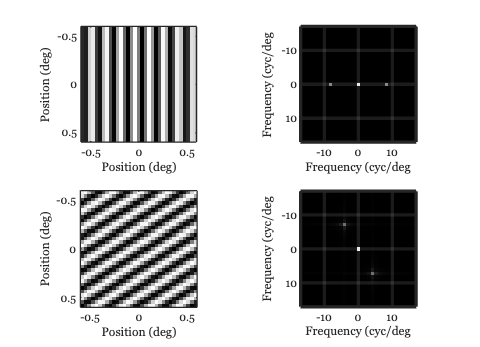

img = sceneGet(scene,'luminance');

% The 2D Fourier transform
imgF = fft2(img);

% We build up the figure
ieFigure;

tiledlayout(2,2)

nexttile
imagesc(x,y,img); axis image
xlabel('Position (deg)'); ylabel('Position (deg)');

nexttile;
imagesc(fullFx,fullFy,abs(fftshift(imgF))); 
axis equal; axis image; colormap(gray);
set(gca, 'Color', 'k'); % Set background color to black
grid on; % Turn on the grid
ax = gca; % Get current axes
ax.GridColor = [0.7 0.7 0.7]; % Set grid color to dark gray
ax.GridLineStyle = '-'; % Set grid line style
ax.LineWidth = 3; % Set grid line thickness
xlabel('Frequency (cyc/deg');
ylabel('Frequency (cyc/deg');

% A different harmonic
params.ang = 45;
[scene,parms] = sceneCreate('harmonic',params);
scene = sceneSet(scene,'fov',1);
img = sceneGet(scene,'luminance');
imgF = fft2(img);

nexttile
imagesc(x,y,img); axis image; 
xlabel('Position (deg)'); ylabel('Position (deg)');
nexttile;
imagesc(fullFx,fullFy,abs(fftshift(imgF))); 
axis equal; axis image; colormap(gray);
set(gca, 'Color', 'k'); % Set background color to black
grid on; % Turn on the grid
ax = gca; % Get current axes
ax.GridColor = [0.7 0.7 0.7]; % Set grid color to dark gray
ax.GridLineStyle = '-'; % Set grid line style
ax.LineWidth = 3; % Set grid line thickness
xlabel('Frequency (cyc/deg');
ylabel('Frequency (cyc/deg');

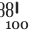

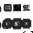

Done.


%{
% Write out the figure as a PNG.
theDir = fullfile(fiseRootPath,'chapters','images','optics');
exportgraphics(gcf,fullfile(theDir,'otf2d.png'));
%}

## End